# Sensitivity analysis - RIDME overtone coefficients

#### Author: Luis Fabregas

In this tutorial we will discuss a simpe example of sensitivity analysis of the fitting of RIDME dipolar signals using overtone coefficients.

## Simulate the data

Let's start by generating some data. We will consider a 7/2-spin system measured by RIDME. Therefore, we will require 7 overtone coefficients to properly simullate the signal. For this particular example we will not include any background. 

clc,clear,clf

%Prepare signal components
t = linspace(-0.1,3.5,200);

%Use a distance-axis with less points to make analysis faster
N = 100;
r = time2dist(t,N);

P = rd_twogaussian(r,[3 0.3 3.5 0.4 0.6]);
lam = 0.52;
%RIDME overtones for spin=+7/2
overtones = [0.36 0.19 0.13 0.11 0.09 0.07 0.05];

%Simulate signal
V = dipolarsignal(t,r,P,'moddepth',lam,'Overtones',overtones,'noiselevel',0.005);

## Regularization fit

Since we know the exact values of the overtone coefficients, let's first add some random error on them to emulate the experimental uncertainty. Next we use those coefficients into the dipolar kernel.

%Add +-50% random error on the overtone coefficients
overtones = (1.5 - rand(size(overtones))).*overtones;

K = dipolarkernel(t,r,lam,'overtonecoeffs',overtones);

We now have all the elements required to fit our distance distribution via regularization. We will use the AIC to select the regularization parameter int he Tikhonov regularization.

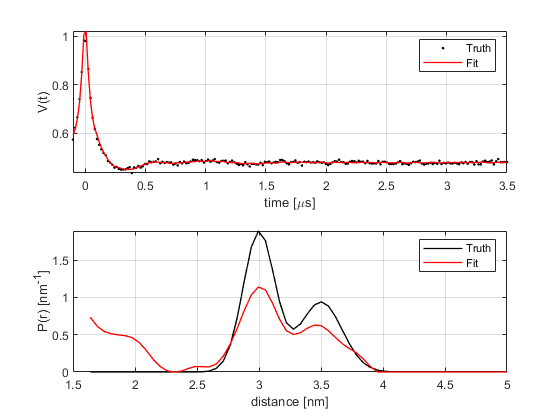

%Fit data via regularization
Pfit = fitregmodel(V,K,r,'tikh','aic');
%Obtain time-domain fit
Vfit = K*Pfit;

%Plot the fit results
subplot(211)
plot(t,V,'k.',t,Vfit,'r','LineWidth',1)
grid on, axis tight,box on
xlabel('time [\mus]')
ylabel('V(t)')
legend('Truth','Fit')

subplot(212)
plot(r,P,'k',r,Pfit,'r','LineWidth',1)
grid on, axis tight,box on
xlim([1.5 5])
xlabel('distance [nm]')
ylabel('P(r) [nm^{-1}]')
legend('Truth','Fit')

## Sensitivity analysis

We now know that we have some unknown error in our RIDME coefficients. The next step is to assess how much uncertainty this will introduce into our fit results. We will study what effect a +-25% error has on our current results. We just need to define the factors for the analysis and prepare the analysis function (see below).  

(Note) Since we are evaluating two levels for seven factors, that makes 128 trials (i.e. 128 times Tikhonov regularization), the calculations can take some time. Since the first four overtones have the largest effect on the signal, for the sake of speed in this tutorial we will analyze only the first 4 overtones. This will lead to 16 trials instead of 128. 

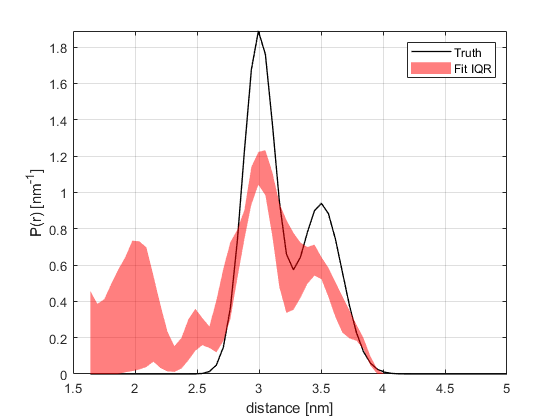

%Define the factors
factors.Over1 = overtones(1)*[0.75 1.25];
factors.Over2 = overtones(2)*[0.75 1.25];
factors.Over3 = overtones(3)*[0.75 1.25];
factors.Over4 = overtones(4)*[0.75 1.25];

%Launch the sensitivity analysis
fcn = @(factors) myanalysis(factors,V,r,t,lam);
stats = sensitivan(fcn,factors);

%Extract the statistical estimators
Pup = stats.p75;
Plo = stats.p25;
Pmed = stats.median;

%Plot sentivity analysis results
clf,hold on
plot(r,P,'k','LineWidth',1)
fill([r fliplr(r)],[Pup; flipud(Plo)],'r','FaceAlpha',0.5,'LineStyle','none')
grid on, axis tight,box on
xlim([1.5 5])
xlabel('distance [nm]')
ylabel('P(r) [nm^{-1}]')
legend('Truth','Fit IQR')

The analysis function must be defined at the end of the script in order to be able to be used as a function. The `sensitivan` function requires a function which only accepts the `factors` structure as an input. However, we can define the function to accept as many inputs as necessary. The function inputs can be adapted by defining a new function handle (e.g. `fcn` above).

Our analysis function will just take the signal, define a new kernel with the current set of overtone coefficients, and fit the data using the AIC-Tikhonov regularization.

function Pfit = myanalysis(factors,V,r,t,lam)

%Extract current factors
overtones(1) = factors.Over1;
overtones(2) = factors.Over2;
overtones(3) = factors.Over3;
overtones(4) = factors.Over4;

K = dipolarkernel(t,r,lam,'OvertoneCoeffs',overtones);

%Do regularization with varying selection method
Pfit = fitregmodel(V,K,r,'tikh','aic');
end